# Using permutation_test function

Created June 9, 2022

clear; clc;
cd('/Users/duncan/Documents/GitHub/permutation_test')

## Simulate some data

mu1 = 0; sigma1 = 1; n1 = 20; 
mu2 = 0.2; sigma2 = 1.3; n2 = 20; 
groupA = normrnd(mu1, sigma1, [n1,1]);
groupB = normrnd(mu2, sigma2, [n2,1]); 

## Two-sided independent difference of means

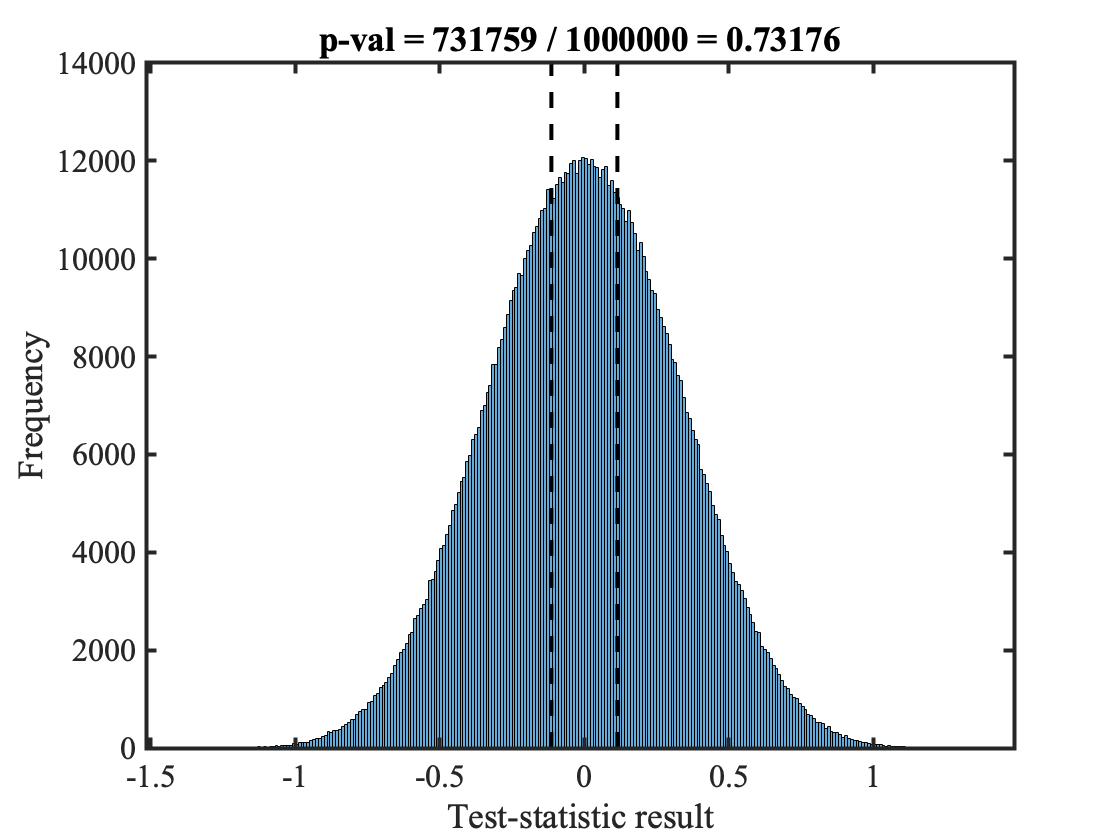

p = 0.7318

p = permutation_test(groupA, groupB, 'vis', true)

## One-sided independent difference of medians with parallel computing

p = permutation_test(groupA, groupB, 'alternative', 'less', 'test_fun', @median, 'parQuick', true)

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


p = 0.7897

delete(gcp()); % shut down parallel pool workers